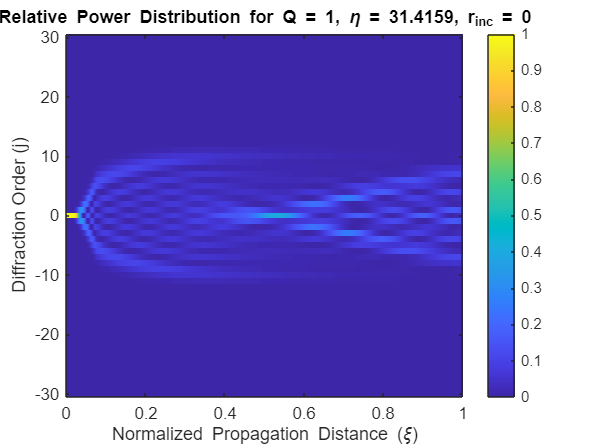

% III b

% Function Raman-Nath Solver
function raman_nath_solver(Q, eta, rinc, jmax)
   
    xi_range = [0, 1];               
    j_vals = -jmax:jmax;               
    N = length(j_vals);               
    cj0 = zeros(N, 1);                 
    cj0(jmax + 1) = 1;                 
    
   
    function dcdxi = raman_nath_odes(xi, cj)
        dcdxi = zeros(N, 1);           
        
      
        for j_idx = 1:N
            j = j_vals(j_idx);
           
            phase_shift = -(1i * Q / 2) * (rinc + j)^2 * cj(j_idx);
            
            
            coupling = 0;
            if j_idx < N
                coupling = coupling + (1i * eta / 2) * cj(j_idx + 1);  
            end
            if j_idx > 1
                coupling = coupling + (1i * eta / 2) * cj(j_idx - 1); 
            end
            
            
            dcdxi(j_idx) = phase_shift + coupling;
        end
    end

    
    [xi_vals, cj_vals] = ode45(@raman_nath_odes, xi_range, cj0);
    
  % Plotting 
    figure;
    imagesc(xi_vals, j_vals, abs(cj_vals').^2);  
    xlabel('Normalized Propagation Distance (\xi)');
    ylabel('Diffraction Order (j)');
    title(['Relative Power Distribution for Q = ', num2str(Q), ', \eta = ', num2str(eta), ', r_{inc} = ', num2str(rinc)]);
    colorbar;
    set(gca, 'YDir', 'normal');  
end

% Input
Q = 1;       
eta = 10*pi; 
rinc = 0;    
jmax = 30;   
raman_nath_solver(Q, eta, rinc, jmax);

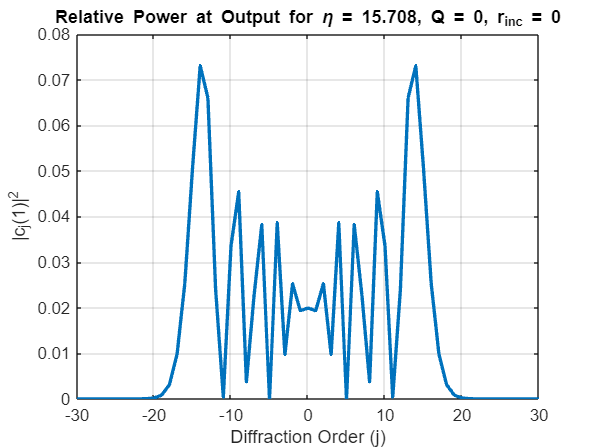

% III c

% Function Raman-Nath solver
function raman_nath_solver_c(Q, eta, rinc, jmax, n_sample_points)
   
    xi_range = linspace(0, 1, n_sample_points);  
    j_vals = -jmax:jmax;                         
    N = length(j_vals);                          
    cj0 = zeros(N, 1);                           
    cj0(jmax + 1) = 1;                           
    
    
    function dcdxi = raman_nath_odes(~, cj)
        dcdxi = zeros(N, 1);  
        
        
        for j_idx = 1:N
            j = j_vals(j_idx);
           
            phase_shift = -(1i * Q / 2) * (rinc + j)^2 * cj(j_idx);
            
            
            coupling = 0;
            if j_idx < N
                coupling = coupling + (1i * eta / 2) * cj(j_idx + 1);  
            end
            if j_idx > 1
                coupling = coupling + (1i * eta / 2) * cj(j_idx - 1); 
            end
            
            
            dcdxi(j_idx) = phase_shift + coupling;
        end
    end

    
    opts = odeset('RelTol', 1e-6, 'AbsTol', 1e-6);  
    [~, cj_vals] = ode45(@raman_nath_odes, xi_range, cj0, opts);
    
    
    cj_final = cj_vals(end, :);
    
% Plotting
    figure;
    plot(j_vals, abs(cj_final).^2, 'LineWidth', 2);
    xlabel('Diffraction Order (j)');
    ylabel('|c_j(1)|^2');
    title(['Relative Power at Output for \eta = ', num2str(eta), ', Q = 0, r_{inc} = 0']);
    grid on;
end

% Input
Q = 0;              
eta = 5*pi;         
rinc = 0;           
jmax = 30;          
n_sample_points = 50000;  

raman_nath_solver_c(Q, eta, rinc, jmax, n_sample_points);

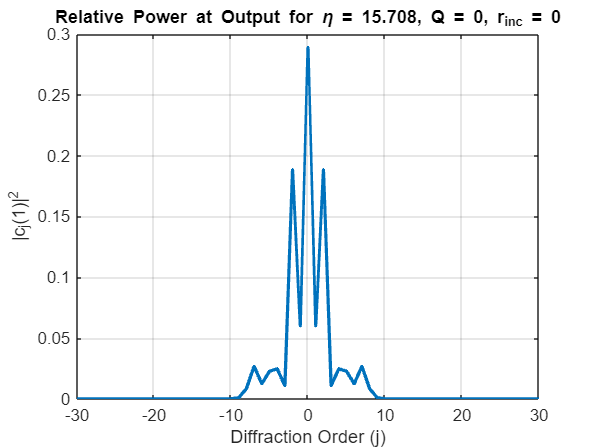

% III d


eta = 5 * pi;    
rinc = 0;        
jmax = 30;        
n_sample_points = 50000;  

% Case 1: Q = 1
Q = 1;
figure;
raman_nath_solver_c(Q, eta, rinc, jmax, n_sample_points);

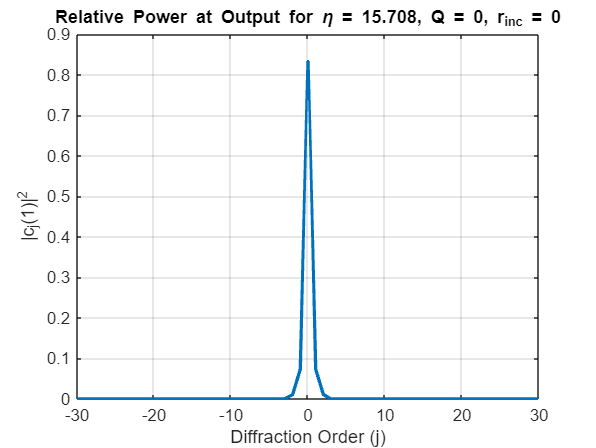


% Case 2: Q = 10
Q = 10;
figure;
raman_nath_solver_c(Q, eta, rinc, jmax, n_sample_points);